# Localización en 2D usando datos de un sensor inercial localizado en L3.

## Carga de los datos

data=load('../simur_data/test.log');
data(1:3,:)

ans =          0    9.7465    0.5188    0.7361   -0.0143    0.0348    0.0233   -0.5298    0.4255    0.0564
    0.0100    9.7374    0.4972    0.7142   -0.0060    0.0357    0.0295   -0.5262    0.4248    0.0556
    0.0200    9.7340    0.4950    0.7074   -0.0212    0.0174   -0.0125   -0.5276    0.4731    0.0562


Los datos se corresponden a la captura de un sensor Xsens. Cada fila es una muestra, y cada columna representa:

[ Tiempo, 3 aceleraciones: vertical, mediolateral (hacia la derecha), anteroposterior,  3 giros: Vert, ML, AP, 3 magneticos:  Vert,ML,AP

Representamos unos pocos pasos para ver las señales de aceleración:

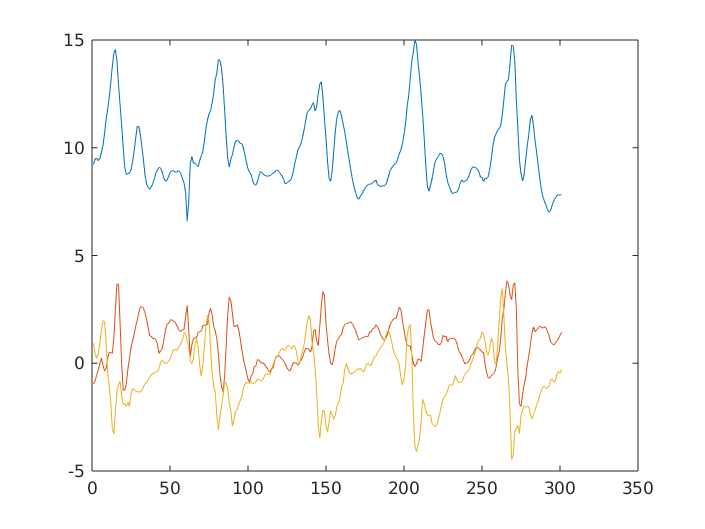

plot(data(1000:1300,2:4));

## Detección de eventos del paso

Separamos las dos aceleraciones en las que detectamos eventos

Acc_X=data(:,4); 
Acc_Z=data(:,2); 

 Inicializamos el sistema de detección de eventos en tiempo real

tiempos=eventos_RT(0,0,'reset')

tiempos = 0

eventosHS=0*Acc_X;
eventosTO=0*Acc_X;

Y lo alimentamos con los datos 1 a 1 como se haría en tiempo real

for k=1:length(Acc_X)
    [hs,to]=eventos_RT(Acc_X(k),Acc_Z(k));
    if (hs~=0)
        eventosHS(k-hs)=1;
    end
    if (to~=0)
        eventosTO(k-to)=1;
    end
end

No se ha encontrado el FF, valor aproximado
No se ha encontrado el FF, valor aproximado
No se ha encontrado el FF, valor aproximado
No se ha encontrado el FF, valor aproximado
No se ha encontrado el FF, valor aproximado


Tenemos ahora una lista con todos los eventos HeelStrike y ToeOff. Junto con avisos de detecciones incorrectas.

Los representamos durante un instante para ver el resultado

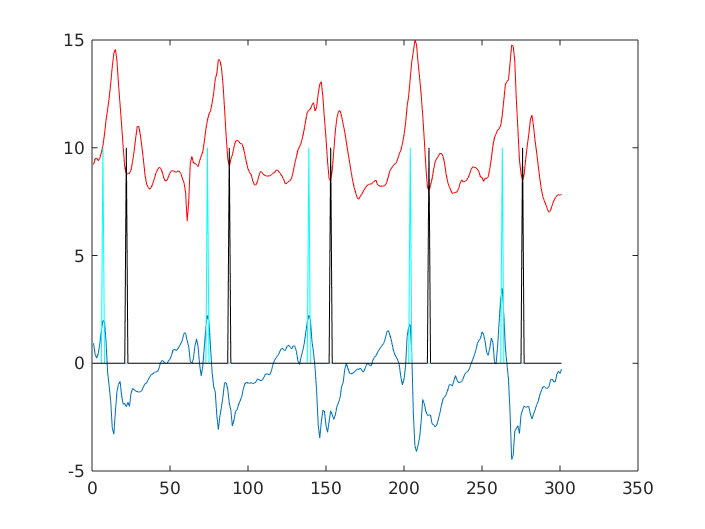

figure; plot(Acc_X(1000:1300)); 
hold on; plot(Acc_Z(1000:1300),'r');
plot(eventosHS(1000:1300)*10,'c');
plot(eventosTO(1000:1300)*10,'k');

## Estimación de las distancias de cada paso

Ahora que tenemos los pasos segmentados, procedemos a calcular cuanto se ha avanzado en cada uno.

Localizamos la muestra en la que está cada HeelStrike

indicesHS=find(eventosHS);

y aplicamos un método de estimación del paso entre cada 2 eventos

distancias=0*Acc_X;
for k=2:length(indicesHS)
    inicio_paso=indicesHS(k-1);
    fin_paso=indicesHS(k);
    if fin_paso-inicio_paso<200 %Si la separación entre eventos es mayor no se estaba caminando
        distancias(fin_paso)=distancia_pendulo(Acc_Z(inicio_paso:fin_paso),100,1);
        %En este ejemplo sabemos que la frecuencia de muestreo es de 100Hz,
        %y suponemos el arco de la pierna de 1m
    end
end

Ilustramos la distancia total avanzada

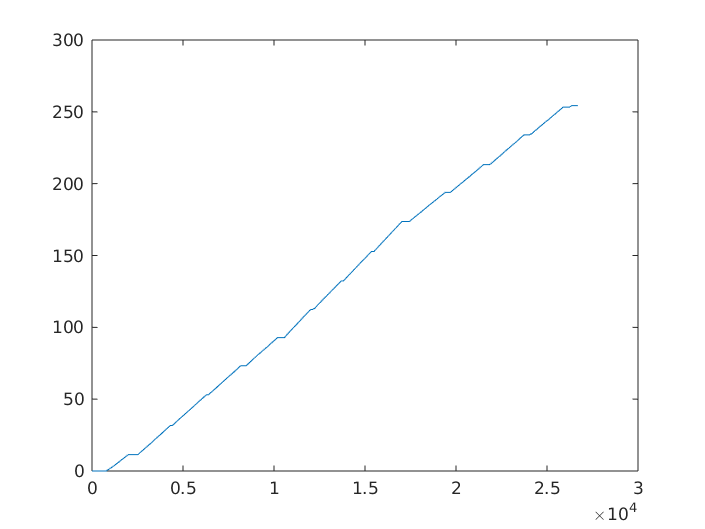

figure; plot(cumsum(distancias));

Y también la correspondiente a los 4 pasos que veíamos antes

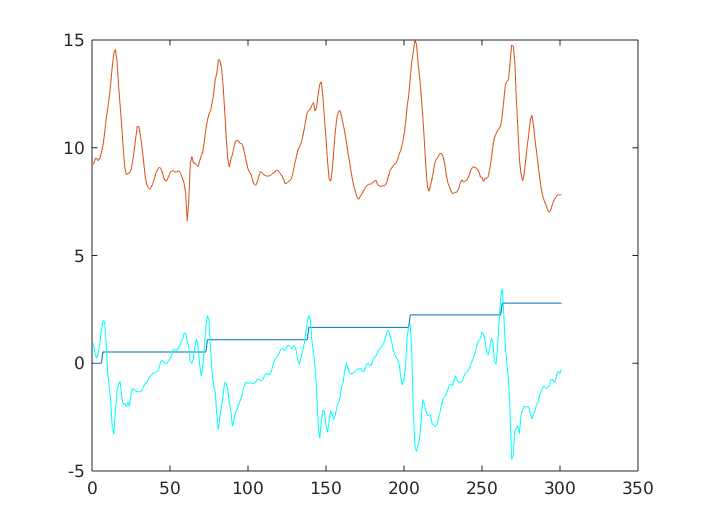

figure; plot(cumsum(distancias(1000:1300)));
hold on; plot(Acc_Z(1000:1300));
plot(Acc_X(1000:1300),'c');

## Estimación de la orientación

Ahora vamos a estimar la orientación en base a los datos del giróscopo.

Tomamos los datos de velocidad de giro vertical del giróscopo:

velgiro=data(:,5);


Despues de 12 giros debería sair 12*pi , pero sale sum(velgiro(1000:25000))/100. Sabemos que se producen 12 giros de 180 entre esos instantes.

El error es:

error=12*pi-sum(velgiro(1000:25000))/100;


Y podemos usarlo para corregir el offset en la velocidad de giro y que salca el valor correcto. El tiempo es 24000 muestras /100Hz


velgiro=velgiro+error/(24000/100);

orientacion=orientaciongiroscopo(velgiro,0,100);

Y dibujamos la orientación instantanea del cuerpo (en grados para el dibujo).

Cada cambio bruso se corresponde con un giro de ida y vuelta

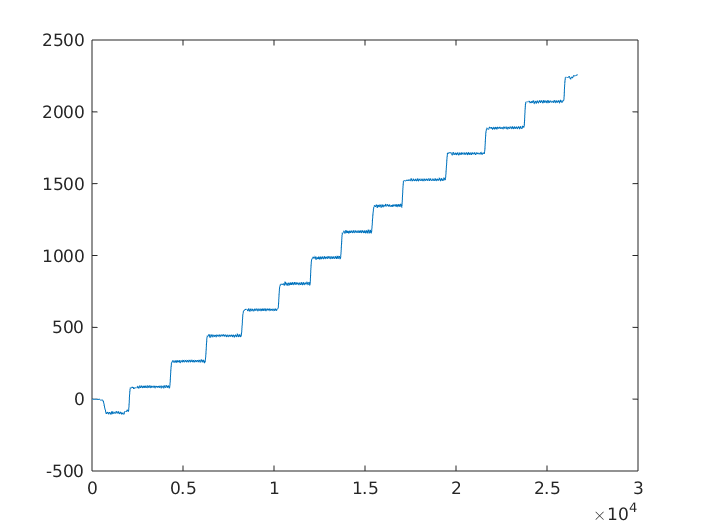

figure; plot(orientacion*180/pi)

Durante los pasos que analizabamos antes no cambia mucho (son en recto)

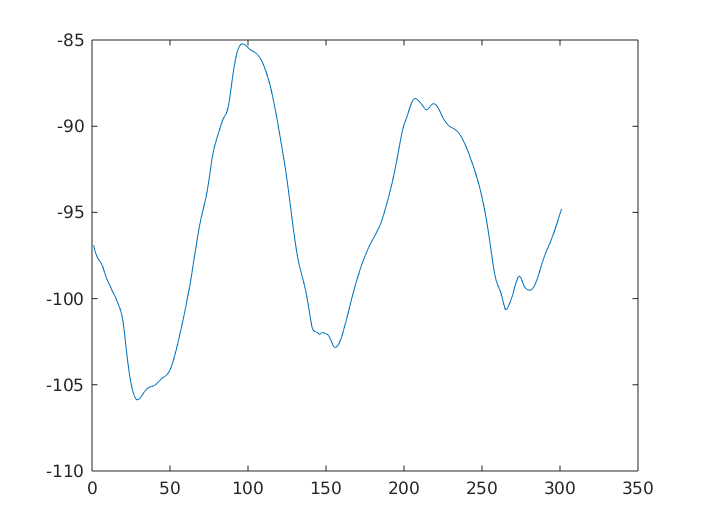

figure; plot(orientacion(1000:1300)*180/pi)

## Cálculo de la posisión 2D.

Combinando ángulo y distancia se calcula la posición x e y a lo largo del tiempo.

posx=0*Acc_X;
posy=0*Acc_X;
for k=2:length(posx)
    posx(k)=posx(k-1)+distancias(k)*cos(orientacion(k));
    posy(k)=posy(k-1)+distancias(k)*sin(orientacion(k));
end

Representamos el resultado

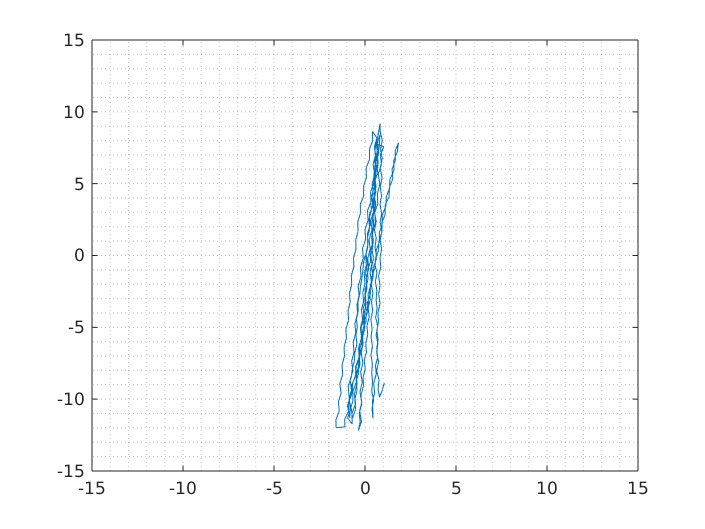

figure;
plot(posx,posy)
axis([-15,15,-15,15])
grid minor

Obtenemos una serie de recorridos de ida y vuelta, prácticamente rectos.